# Naive random sampling, Latin Hyper cube & Sobol sequence sampling 

clear;
clc;

% Construct the parameter distrubtion for Sarah model

size = 10000;

amp_pd = makedist('Uniform','lower',0,'upper',1);
phase_pd = makedist('Uniform','lower',0,'upper',24);

Kd_pd_log= makedist('Uniform','lower',-1.58,'upper',1.415);
Kd_pd = 10.^random(Kd_pd_log,[size,1]);

params = {amp_pd phase_pd Kd_pd amp_pd phase_pd};

# Naive random sampling

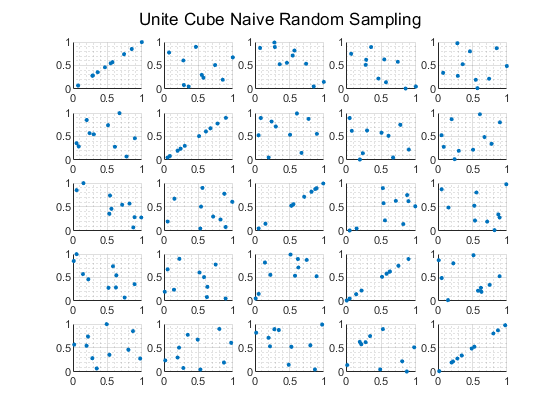

% generate parameter space for variance calculation
N = 10;
d = 5;

Var_Cube_Naive = rand(N,d);
% Var_Parameter = zeros(N,d);
% for i=1:d
%     pd = params{i};
%     if isa(pd,'double')
%         Var_Parameter(:,i) = datasample(pd,N);  
%     else
%         Var_Parameter(:,i) = icdf(pd,Var_Cube_Naive(:,i));
%     end
% end

% pairwise 2D scatter plots of Unit Cube
figure;
fig_index = 1;
for i=1:d
    for j=1:d
   
            subplot(d,d,fig_index);
            scatter(Var_Cube_Naive(:,i),Var_Cube_Naive(:,j),10,'filled')
            grid on
            grid minor
            fig_index = fig_index+1;
            
    end
end
sgtitle('Unite Cube Naive Random Sampling')

# Latin Hyper Cube Sampling

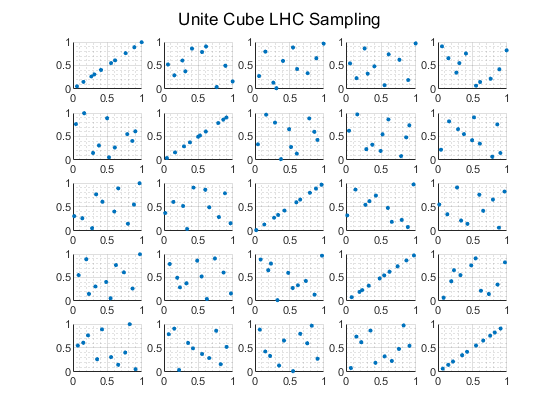

rng default % For reproducibility
Var_Cube_LHC = lhsdesign(N,d);


% pairwise 2D scatter plots of Unit Cube
figure;
fig_index = 1;
for i=1:d
    for j=1:d
   
            subplot(d,d,fig_index);
            scatter(Var_Cube_LHC(:,i),Var_Cube_LHC(:,j),10,'filled')
            grid on
            grid minor
            fig_index = fig_index+1;
            
    end
end
sgtitle('Unite Cube LHC Sampling')

# Sobol sequence Sampling

The goal of quasi-random sequence is not to approximate true randomenss, rather seek to fill the parameter space uniformly. Sobol sequences, use a base of 2 to form partition of unit interval.

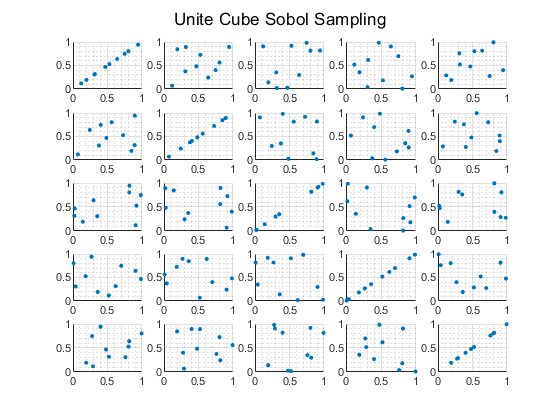

rng default % For reproducibility

p = sobolset(d,'Skip',1e3,'Leap',1e2);

% scrambling
p = scramble(p,'MatousekAffineOwen');
% generate points using function 'net', which returns the first n points
% from Sobolset object
Var_Cube_Sobol = net(p,N);

% pairwise 2D scatter plots of Unit Cube
figure;
fig_index = 1;
for i=1:d
    for j=1:d
   
            subplot(d,d,fig_index);

            scatter(Var_Cube_Sobol(:,i),Var_Cube_Sobol(:,j),10,'filled')
            
            grid on
            grid minor
            fig_index = fig_index+1;
            
    end
end
sgtitle('Unite Cube Sobol Sampling')

Compare Naive Random, LHC, Sobol Sampling Unit Cube

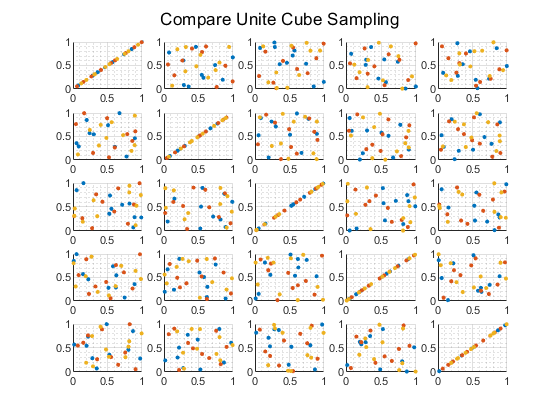

figure;
fig_index = 1;
for i=1:d
    for j=1:d
   
            subplot(d,d,fig_index);
            scatter(Var_Cube_Naive(:,i),Var_Cube_Naive(:,j),10,'filled')
            hold on;
            scatter(Var_Cube_LHC(:,i),Var_Cube_LHC(:,j),10,'filled')
            hold on;
            scatter(Var_Cube_Sobol(:,i),Var_Cube_Sobol(:,j),10,'filled');
            hold off;
            
            grid on
            grid minor
            fig_index = fig_index+1;
            
    end
end
sgtitle('Compare Unite Cube Sampling')

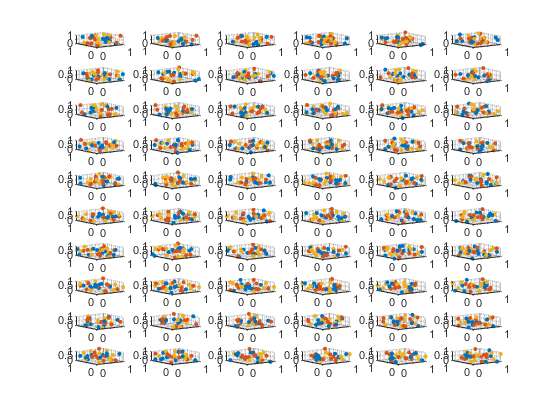

% 3D parameter space scatter plots comparision
figure;
fig_index = 1;
for i=1:d
    for j=1:d
        for k=1:d
            if i ~= j && j~= k && i~= k
                subplot(10,6,fig_index);
                scatter3(Var_Cube_Naive(:,i),Var_Cube_Naive(:,j),Var_Cube_Naive(:,k),10,'filled');
                hold on;
                scatter3(Var_Cube_LHC(:,i),Var_Cube_LHC(:,j),Var_Cube_LHC(:,k),10,'filled');
                hold on;
                scatter3(Var_Cube_Sobol(:,i),Var_Cube_Sobol(:,j),Var_Cube_Sobol(:,k),10,'filled');
                hold off;
                
                grid on
                grid minor
                fig_index = fig_index+1;
            end
        end   
    end
end